 %% ======================================================================
  %  Simulacion - Circuito RC de Primer Orden                                                                                                                                           
  %  Equipo: Malvados y Asociados                      
  %  Ref: Hayt, Engineering Circuit Analysis 8th Ed. - Cap 8, Sec 8.9                                                                                                                   
  %  Bug MATLAB R2025b Linux: se usa 'LineJoin','chamfer'                                                                                                                               
  %  ======================================================================                                                                                                             
                                                       
  %% Parametros del circuito (Hayt Sec 8.9)                                                                                                                                             
  R   = 1e3;                                                                                                                                                                            
  C   = 1e-6;                                                                                                                                                                           
  tau = R * C;                                                                                                                                                                          
  V   = 9;                                                                                                                                                                              
                                                                                                                                                                                        
  fprintf('R = %d Ohm\n', R)                           

R = 1000 Ohm


  fprintf('C = %.0e F\n', C)                                                                                                                                                            

C = 1e-06 F


  fprintf('tau = %.1f ms\n', tau*1e3)                  

tau = 1.0 ms


  fprintf('V = %d V\n', V)                                                                                                                                                              

V = 9 V


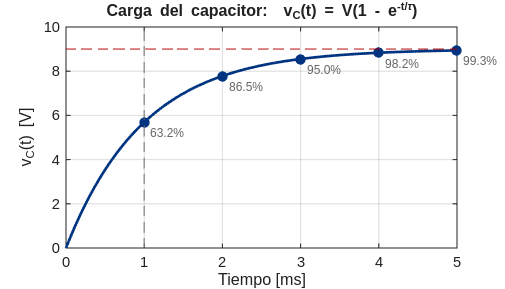

                                                  
  %% Colores formales                                                                                                                                                                   
  azul = [0.0 0.2 0.5];                           
  rojo = [0.7 0.0 0.0];                                                                                                                                                                 
  gris = [0.4 0.4 0.4];                                                                                                                                                                 
  ruta = '/home/diegos/Documents/Robotica/Identificacion_de_sistemas/docs/reporte/';
                                                                                                                                                                                        
  %% Respuesta basica: carga y descarga           
  t = linspace(0, 5*tau, 5000);                                                                                                                                                         
  v_carga    = V * (1 - exp(-t/tau));                                                                                                                                                   
  v_descarga = V * exp(-t/tau);                   
                                                                                                                                                                                        
  % Carga                                              
  fig1 = figure('Color','w', 'Position', [100 100 700 400]);                                                                                                                            
  plot(t*1e3, v_carga, '-', 'Color', azul, 'LineWidth', 2, 'LineJoin', 'chamfer')                                                                                                       
  hold on                                                                                                                                                                               
  yline(V, '--', 'Color', rojo, 'LineWidth', 1);                                                                                                                                        
  xline(tau*1e3, '--', 'Color', gris, 'LineWidth', 1);                                                                                                                                  
  for k = 1:5                            
      val = V * (1 - exp(-k));                                                                                                                                                          
      plot(k*tau*1e3, val, 'o', 'Color', azul, 'MarkerSize', 6, 'MarkerFaceColor', azul)                                                                                                
      text(k*tau*1e3 + 0.08, val - 0.5, sprintf('%.1f%%', val/V*100), 'FontSize', 9, 'Color', gris)                                                                                     
  end                                                                                                                                                                                   
  xlabel('Tiempo [ms]', 'FontSize', 12)                                                                                                                                                 
  ylabel('v_C(t) [V]', 'FontSize', 12)                 
  title('Carga del capacitor:  v_C(t) = V(1 - e^{-t/\tau})', 'FontSize', 13)                                                                                                            
  grid on                                                                                                                                                                               
  set(gca, 'FontSize', 11)                                                                                                                                                              
  saveas(fig1, fullfile(ruta, 'fig_carga.png'))                                                                                                                                         

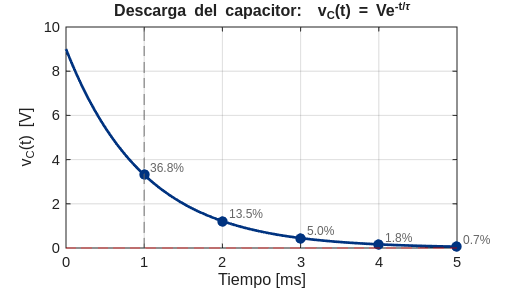

                                                                                                                                                                                        
  % Descarga                                           
  fig2 = figure('Color','w', 'Position', [100 100 700 400]);                                                                                                                            
  plot(t*1e3, v_descarga, '-', 'Color', azul, 'LineWidth', 2, 'LineJoin', 'chamfer')
  hold on                                                                                                                                                                               
  yline(0, '--', 'Color', rojo, 'LineWidth', 1);       
  xline(tau*1e3, '--', 'Color', gris, 'LineWidth', 1);                                                                                                                                  
  for k = 1:5                                     
      val = V * exp(-k);                                                                                                                                                                
      plot(k*tau*1e3, val, 'o', 'Color', azul, 'MarkerSize', 6, 'MarkerFaceColor', azul)
      text(k*tau*1e3 + 0.08, val + 0.3, sprintf('%.1f%%', val/V*100), 'FontSize', 9, 'Color', gris)                                                                                     
  end                                                                                                                                                                                   
  xlabel('Tiempo [ms]', 'FontSize', 12)                
  ylabel('v_C(t) [V]', 'FontSize', 12)                                                                                                                                                  
  title('Descarga del capacitor:  v_C(t) = Ve^{-t/\tau}', 'FontSize', 13)
  grid on                                                                                                                                                                               
  set(gca, 'FontSize', 11)                                                                                                                                                              
  saveas(fig2, fullfile(ruta, 'fig_descarga.png'))                                                                                                                                      

                                                                                                                                                                                        
  fprintf('Figuras carga/descarga exportadas.\n')                                                                                                                                       

Figuras carga/descarga exportadas.


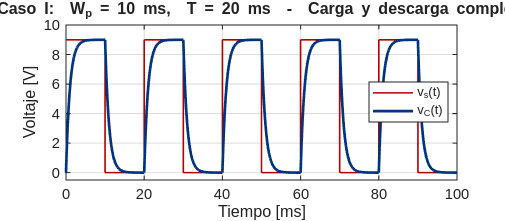

Exportada: fig_caso1.png


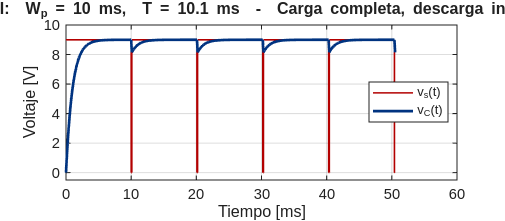

Exportada: fig_caso2.png


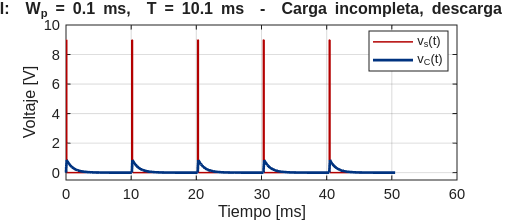

Exportada: fig_caso3.png


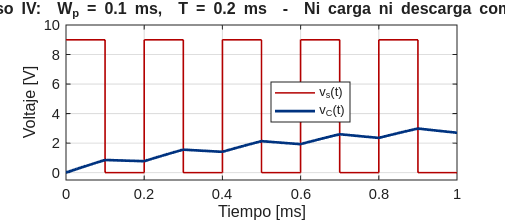

Exportada: fig_caso4.png


                                                  
  %% 4 Casos - Tren de pulsos (Hayt Table 8.1, Fig 8.48/8.49)                                                                                                                           
  casos = struct( ...                                                                                                                                                                   
      'Wp',     {10e-3,    10e-3,     0.1e-3,     0.1e-3}, ...
      'T',      {20e-3,    10.1e-3,   10.1e-3,    0.2e-3}, ...                                                                                                                          
      'nombre', {'Caso I:  W_p = 10 ms,  T = 20 ms', ...
                 'Caso II:  W_p = 10 ms,  T = 10.1 ms', ...                                                                                                                             
                 'Caso III:  W_p = 0.1 ms,  T = 10.1 ms', ...
                 'Caso IV:  W_p = 0.1 ms,  T = 0.2 ms'}, ...                                                                                                                            
      'desc',   {'Carga y descarga completa', ...      
                 'Carga completa, descarga incompleta', ...                                                                                                                             
                 'Carga incompleta, descarga completa', ...
                 'Ni carga ni descarga completa'} ...                                                                                                                                   
  );                                     
                                                                                                                                                                                        
  for i = 1:4                                          
      Wp = casos(i).Wp;                                                                                                                                                                 
      T  = casos(i).T;                   
      N  = 5;                                                                                                                                                                           
   
      t_vec  = [];                                                                                                                                                                      
      vc_vec = [];                       
      vs_vec = [];                       
      V0 = 0;                                     
                                                       
      for n = 0:N-1
          tc  = linspace(0, Wp, 500);
          vcc = V + (V0 - V) * exp(-tc / tau);                                                                                                                                          
          V1  = vcc(end);                
          td  = linspace(0, T - Wp, 500);                                                                                                                                               
          vcd = V1 * exp(-td / tau);                   
                                         
          t_vec  = [t_vec,  n*T + tc,           n*T + Wp + td];
          vc_vec = [vc_vec, vcc,                vcd];                                                                                                                                   
          vs_vec = [vs_vec, V*ones(size(tc)),   zeros(size(td))];
          V0 = vcd(end);                                                                                                                                                                
      end                                                                                                                                                                               
                                                       
      fig = figure('Color','w', 'Position', [100 100 800 350]);                                                                                                                         
      plot(t_vec*1e3, vs_vec, '-', 'Color', rojo, 'LineWidth', 1.2, 'LineJoin', 'chamfer')
      hold on                                                                                                                                                                           
      plot(t_vec*1e3, vc_vec, '-', 'Color', azul, 'LineWidth', 2, 'LineJoin', 'chamfer')
      xlabel('Tiempo [ms]', 'FontSize', 12)                                                                                                                                             
      ylabel('Voltaje [V]', 'FontSize', 12)       
      title(sprintf('%s  -  %s', casos(i).nombre, casos(i).desc), 'FontSize', 12)
      legend('v_s(t)', 'v_C(t)', 'Location', 'best', 'FontSize', 10)                                                                                                                    
      grid on                                          
      set(gca, 'FontSize', 11)                                                                                                                                                          
      ylim([-0.5 10])                                  
      saveas(fig, fullfile(ruta, sprintf('fig_caso%d.png', i)))                                                                                                                         
      fprintf('Exportada: fig_caso%d.png\n', i)
  end                                                                                                                                                                                   

                                                       
  fprintf('\nTodas las figuras exportadas en docs/reporte/\n') 


Todas las figuras exportadas en docs/reporte/
